# 1 Reconstructing EEG/MEG activity using beamforming

This document contains the MATLAB exercises that form part of the course “Neuroimaging II” relating to the scanning methods, specifically using beamforming.

## 1.1 Introduction

Beamforming is the third type of strategy that can be used for source reconstruction of EEG/MEG data that is discussed in this course.

As a brief recapitulation, the ***first strategy*** is the dipole fitting approach, where the underlying assumption is that the pattern in the observed data can be explained by a limited number of neural sources that are modelled as equivalent current dipoles. The goal is now to find the parameters for the model that optimally explains the observed sensor-level topography. These parameters pertain to the number, location and orientation of the dipoles, and the optimal model is determined by minimizing the error between the model and the observed data.

The ***second strategy*** we discussed was distributed source modeling, where minimum norm estimation was treated in some more detail. In this approach, the observed data is assumed to be determined by a mixing of many active sources, where the number of active sources is much higher than the number of observed channels. This leads to an underdetermined problem, and one way to solve this is to assume that a good guess of the distribution of the source amplitudes has the lowest possible norm. One important feature of distributed source models is the fact that the amplitudes of the individual sources are estimated in a single inversion step.

The ***third strategy*** that will be treated here is a so-called scanning method (we will specifically be dealing with beamforming), where the amplitude at a predefined set of source locations is estimated iteratively, that is, for one source location at a time. This difference with distributed source modeling has some important consequences, which we will return to later in these exercises. The key feature of beamforming is that no prior assumption about the number of sources is made. Rather, for each location that we choose to evaluate, we ask ourselves the question: 'What would the the best estimate of the dipole moment at this location?’ It turns out, that if we assume the underlying sources to be uncorrelated over time we can get quite good estimates of our sources’ activation time courses using beamforming.

The 'best estimate’ in the previous question is more specifically operationalised as the estimate that best captures the activity that can originate from that location while optimally suppressing interference from sources at other locations. When we use so-called adaptive beamformers for this, we need not only the biophysically constraining forward model (i.e., the leadfield matrix), we also need the sensor-level data, or more specifically the sensor-level covariance matrix. Before we will start playing with the beamformer and get a feel for how and why it works, the next section will deal with the concept of the sensor-level covariance matrix.

## 1.2 Getting started: tips on how to approach the exercises

The best way to approach the exercises is to create a MATLAB-script that can be used to copy-and-paste the MATLAB-code in the instructions, and allows you to play around with various parameter settings etc. You can open a new script in the MATLAB-editor by typing edit on the command line, or by going to File->New->Script. Next, you can save each script as a separate file in your course folder.

% set up the MATLAB path 
ni2_startup
ft_version

## 2 The sensor covariance matrix: a key ingredient for the beamformer

After this section you will

- Understand the concept of a covariance matrix.

- Argue that the sensor covariance matrix represents a mixture of the leadfield outer products of all pairs of active sources.

- Understand that, if the sources underlying the sensor covariance matrix are uncorrelated over time, the covariance matrix reduces to a weighted sum of the leadfield outer products of only the active sources.

## 2.1 The concept of covariance

In the following we will use `X` and `Y` to represent vectors rather than matrices, to allow for formatting an element of that vector with a subscript as `Xi`. 

The covariance between two variables (in our case time series) is defined as:

% cov(X, Y) = ∑ (Xi-mean(X)) * (Yi-mean(Y)) / (n-1)

If, for simplicity, we assume the vectors x and y to have a mean value of 0, this equation reduces to:

% cov(X, Y) = ∑ (Xi * Yi) / (n-1)

In words: take the element-wise product of the elements in the vectors x and y, and sum these products. Finish by normalizing with `(n-1)`, where n is the number of elements in the vectors.

A further simplification of this formula, assuming the vectors X and Y being row vectors, using matrix algebra (remember what you have learnt from matrix multiplication):

% cov(X, Y) = X * Y' / (n-1)

Sometimes we even forget about the normalization term `(n-1)`, so we end up with `X*Y'`.

Anyway, what we need to know about the covariance that it quantifies the extent to which variables x and y tend to covary (what’s in a name?) linearly. In other words, if the sign of the covariance is positive, it reflects the overall tendency of y to go up if x goes up (and vice versa). If the sign of the covariance is negative, y has the tendency to go down if x goes up, and vice versa. If the covariance is very close to 0, x and y don’t tend to covary.

The concept of covariance is very closely related to the concept of correlation and regression, but this is not the time to discuss it in further detail.

Let’s start with creating a few vectors in MATLAB to further illustrate the concept of covariance. First, we will create two vectors x and y, with the mean value subtracted:

x = randn(1, 100);
x = x-mean(x);

y = randn(1, 100);
y = y-mean(y);

Now we can compute the covariance between x and y with just a simple command:

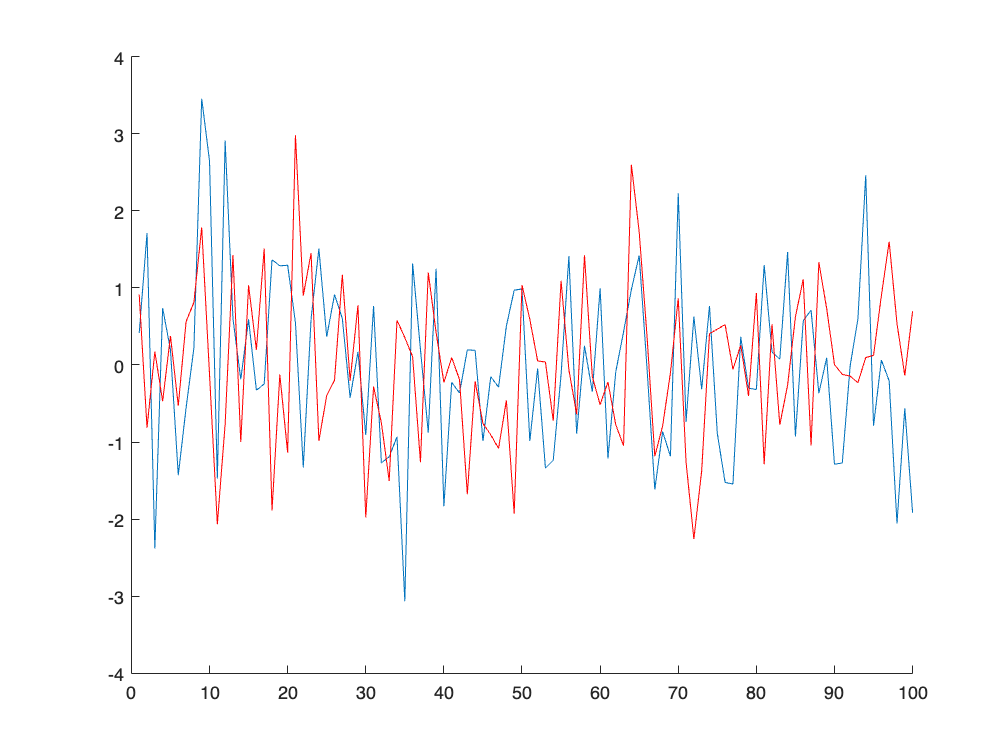

covxy = (x*y')/99;

We can also visualize these vectors:

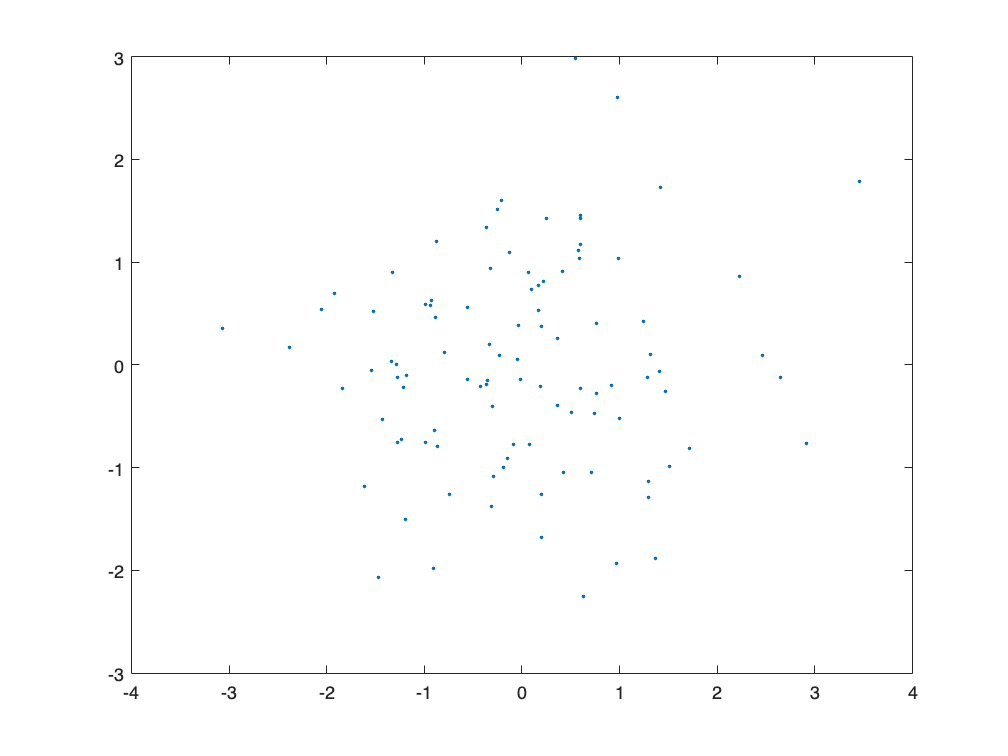

figure; hold on; plot(x); plot(y, 'r');

figure; plot(x, y, '.');

The second figure is a so-called scatter plot, which shows that the individual pairs of observations (the corresponding entries in the vectors x and y) are distributed all over the Cartesian xy-plane.

***Looking at the scatter plot with x along the horizontal and y along the vertical axis. Are the two correlated?***

Now we can introduce covariance between the vectors x and y by adding some shared signal to the vectors:

a = 1;
b = 1;
c = randn(1, 100);

x2 = x  + a .* c;
x2 = x2 - mean(x2);

y2 = y  + b .* c;
y2 = y2 - mean(y2);

covxy2 = (x2*y2')/99;

***Again make a scatter plot. ***

***What is the correlation coefficient between x2 and y2? Explain the (approximate) number that you get (hint: think about how the correlation relates to explained variance). ***

Up until now we have explored the covariance between two variables represented as vectors. It may come as no surprise that we can perform the same multiplication operation to a pair of matrices. If we consider a sensor-level data matrix X with the channels in the rows and the time points in the columns (and with the mean across columns subtracted from each column), when we do `X*X'` we will get an n x n covariance matrix (strictly speaking scaled with the number of time points minus one: for the following let’s forget about this scaling, and also let’s assume the individual rows to have a mean value of 0), where n is the number of channels. Each element `c(i,j)` in this matrix, let’s call this matrix `C` reflects the covariance between the i-th and j-th channel. 

There are a few remarks to be made about a covariance matrix:

- When a covariance matrix is mirrored across the main diagonal of the matrix, you will get the same values.

- The elements on the main diagonal contain the auto-covariance between each channel and itself, and are always positive values. These values represent the variance of each channel.

***Compute some normally distributed random data for 32 channels and 100 timepoints and represent this in a single matrix. ***

***Now compute the covariance between all channels; this can be represented in a nchan x nchan matrix. You can use either for loops, or the corresponding function in MATLAB. ***

***Plot the covariance matrix using ***`imagesc`*** and add a colorbar to the figure***`. ` 

## 2.2 The sensor covariance gives information about the mixing process

Let’s go back now to our basic observation model: `X = L*S+n`. If we now change this equation to include the individual contributions of the single sources s1, s2, ..., up to `sn`, and forget about the noise we get:

% X = l1*s1 + l2*s2 + ... + ln*sn

When we compute `X*X'` and observe the individual terms in X we are essentially doing the following:

% C = (l1*s1 + l2*s2 + ... +ln*sn) * (l1*s1 + l2*s2 + ... +ln*sn)'

Note that here we are ignoring for now the normalization, i.e., the division by N-1.

There is a basic rule in matrix algebra that states that `(A*B)'` is the same as `B'*A'`. Using this rule, and taking all the individual terms in the above equation out of the brackets, we get:

% C = l1*s1*s1'*l1' + l2*s2*s1'*l1' + ... + ln*sn*s1'*l1' + ...
%     l1*s1*s2'*l2' + l2*s2*s2'*l2' + ... + ln*sn*s2'*l2' + ...
%     ...
%     l1*s1*sn'*ln' + l2*s2*sn'*ln' + ... + ln*sn*sn'*ln'

Now the above equation looks complicated, but if we realize that `si*sj'` represents the covariance (or auto-covariance) between the sources i and j, and that these are scalar values (which means that it does not matter in which order you multiply this in a matrix multiplication), we can rewrite the above equation as:

% C =  var(s1)   *l1*l1' + cov(s2,s1)*l2*l1' + ... + cov(sn,s1)*ln*l1' + ...
%      cov(s1,s2)*l1*l2' + var(s2)   *l2*l2' + ... + cov(sn,s2)*ln*l2' + ...
%      ...  
%      cov(s1,sn)*l1*ln' + cov(s2,sn)*l2*ln' + ... + var(sn)   *ln*ln'

The terms `li*lj'` are also called vector outer-products, so in words the above equation means that the covariance matrix can be represented as a *weighted sum* of the leadfield outer-products between all *pairs of sources*, where the weights are based on the covariance between the corresponding pairs of sources.

This is a very important feature of the covariance matrix that is exploited by the beamformer, and is also exploited when we unmix the data matrix based on a principal components analysis (which could be the topic of another session).

## 3 Computing a beamformer solution

After this section, you will

- Understand the basic recipe for a beamformer analysis.

- Understand that the quality of the reconstruction critically depends on the quality of the estimate of the covariance matrix.

## 3.1 The formulation of the beamforming algorithm.

As already mentioned in the introduction section, the beamforming approach is a so-called scanning method, where we investigate a set of locations in the brain sequentially, where the question asked repeatedly is 'What would be the best estimate of the dipole moment at *this* location?’.

For each of the locations investigated the beamformer algorithm computes a spatial filter, also known as a set of weights (hence the convention to denote the spatial filter with the letter w) that fulfills two criteria:

- The so-called filter gain is equal to 1.

- The filter output should have minimum variance.

The second criterion is specific to the type of beamformer we are typically using, which is known as the minimum-variance beamformer.

The first criterion of a filter gain of 1 is nothing else than 'what you get is what you see’. In other words, the amplitude of the source signal that is coming from a particular location in the brain (which is represented at the channels by the leadfield from that location) should not be attenuated nor amplified by the spatial filter that is estimated for that location. In a mathematical formula this means `wi' * li = 1`. 

The second criterion aims that activity that is not coming from the location under investigation does not affect ('leak into’) the estimate we’re currently interested in. 'Filter output’ here means the estimated source activity. It makes sense to require the *variance* of this filter output to be as low as possible, because if we are investigating a location from which no source activity is emanating, we want the estimated activity to be as low as possible.

It turns out that the two criteria expressed above are fulfilled by a spatial filter computed as:

% w' = inv(lf'*inv(C)*lf) * lf' * inv(C)   

The beamformer makes an accurate reconstruction of the time course of the underlying sources provided the individual sources are uncorrelated over time. In reality neural sources are hardly even totally uncorrelated, but in practical situations the beamformer is still tolerant against moderate levels of source correlation (more about this later). It can be easily seen that the above formulation satisfies criterion 1:

% w'*lf = inv(lf'*inv(C)*lf) * (lf'*inv(C)*lf) = I

The proof that it also satisfies the second criterion can be demonstrated with Lagrange multipliers (see https://en.wikipedia.org/wiki/Lagrange_multiplier), but this falls beyond the scope of this course.

The filter output or estimated source activity is defined as `w'*X`

**Assume that we have data corresponding to 64 channels and and 1000 time points and that we want to use the beamformer filter to estimate the activity of a single dipole with known orientation, i.e., using a leadfield with 1 column.**

**What is the size of the data matrix **`X and `**the size of the data covariance matrix?**

**What is the size of the filter **`w`**?**

**What is the size of the result of the multiplication **`w'*X`**?**

## 3.2 Beamforming of simulated data. 

Let us now create some simulated data to demonstrate the beamformer.

sensors   = ni2_sensors('type', 'meg');
headmodel = ni2_headmodel('type', 'spherical', 'nshell', 1);

leadfield1 = ni2_leadfield(sensors, headmodel, [-2 -8  3 -1 0 0]);     % position 1110 in the grid

using gradiometers specified in the configuration
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 1 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 2 seconds and required the additional allocation of an estimated 12 MB


leadfield2 = ni2_leadfield(sensors, headmodel, [-5  0  6  1 0 0]);     % position 2342 in the grid

using gradiometers specified in the configuration
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 1 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 1 seconds and required the additional allocation of an estimated 3 MB


leadfield3 = ni2_leadfield(sensors, headmodel, [ 5  0  6  0 1 0]);     % position 2352 in the grid

using gradiometers specified in the configuration
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 1 seconds and required the additional allocation of an estimated 2 MB


leadfield4 = ni2_leadfield(sensors, headmodel, [ 4 -2  7  0 0.2 0.7]); % position 2674 in the grid

using gradiometers specified in the configuration
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
1 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 0 MB
computing leadfield
computing leadfield 1/1

the call to "ft_prepare_leadfield" took 1 seconds and required the additional allocation of an estimated 0 MB


[s1, t] = ni2_activation('latency', .45, 'frequency',  3);
[s2, t] = ni2_activation('latency', .50, 'frequency', 10);
[s3, t] = ni2_activation('latency', .50, 'frequency', 15);
[s4, t] = ni2_activation('latency', .55, 'frequency', 30);

sensordata = leadfield1*s1 + leadfield2*s2 + leadfield3*s3 + leadfield4*s4 + randn(301, 1000)*1e-9;

***Make a figure with 4 subplots underneath each other and plot the activity of source 1 to 4 (along the vertical axis) versus time (along the horizontal axis).***

***Make a figure with the sensordata versus time. Do you recognize the source activity?***

We are first going to compute the beamformer spatial filters by hand, to demonstrate the recipe. As mentioned in the previous section, the beamformer needs the sensor-level covariance matrix and the leadfields for the locations at which the spatial filters are going to be estimated. For now we will be using a 3-dimensional regular 'grid’ of dipole positions, where the source locations are 1 cm apart. Also, we will use FieldTrip to efficiently compute the leadfields. In principle we could achieve the same using the `ni2_leadfield` function, but the first approach is much faster:

sourcemodel = ni2_sourcemodel('type', 'grid', 'resolution', 1);

cfg = [];
cfg.sourcemodel = sourcemodel;
cfg.grad        = sensors;
cfg.headmodel   = headmodel;
sourcemodel = ft_prepare_leadfield(cfg);

using gradiometers specified in the configuration
creating sourcemodel based on user specified dipole positions
using gradiometers specified in the configuration
1662 dipoles inside, 1948 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 1 MB
computing leadfield
computing leadfield 1662/1662

the call to "ft_prepare_leadfield" took 3 seconds and required the additional allocation of an estimated 2 MB


L = cat(2, sourcemodel.leadfield{sourcemodel.inside});

***sWhat is the size of the matrix L?***

We also need the covariance of the sensor-level data:

M = mean(sensordata, 2);
M = repmat(M, 1, 1000);
C = ((sensordata-M)*(sensordata-M)')./999;

Now we also compute the inverse of the covariance matrix, because it will be used repeatedly. When it has to be recomputed each time again it slows down the computations.

iC = inv(C);

for ii=1:size(L, 2)/3
  indx = (ii-1)*3 + (1:3);
  Lr = L(:, indx);  % Lr is the Nx3 leadfield matrix for source r
  wbf(indx,:) = pinv(Lr'*iC*Lr)*Lr'*iC;
end

sbf = wbf * sensordata;

***Explain what the variable ***`indx `***is and how it is used.***

We can now inspect the reconstructed source time course at the locations at which activity was simulated. Note that if we don't constrain the orientation of the sources (i.e., use a 3-column leadfield per location) we will get a 3-row spatial filter per location and hence also estimates for the x, y and z component of the activity. 

Since we only did the computations for the grid positions inside the head, we have to go from the original 3D grid indices that covers a square regular grid (inside *and* outside the head) to the list of estimations that are only for the inside positions.

***How many grid positions are there in the complete grid?***

***How many positions are there inside the head?***

***Make a plot of all grid positions and a plot of only the grid positions that are inside the head. You can use plot3, axis equal and axis vis3d.***

index = 1:numel(sourcemodel.inside);               % these are _all_ source positions, including the ones outside the brain
index1110 = find(index(sourcemodel.inside)==1110)  % find the index of source position 1110, only considering the ones inside the brain

index1110 = 744

index2342 = find(index(sourcemodel.inside)==2342)

index2342 = 1426

index2352 = find(index(sourcemodel.inside)==2352)

index2352 = 1436

index2674 = find(index(sourcemodel.inside)==2674)

index2674 = 1536

sel1110 = (index1110-1)*3 + (1:3)                  % find the three columns corresponding to source position 1110

sel1110 =         2230        2231        2232


sel2342 = (index2342-1)*3 + (1:3)

sel2342 =         4276        4277        4278


sel2352 = (index2352-1)*3 + (1:3)

sel2352 =         4306        4307        4308


sel2674 = (index2674-1)*3 + (1:3)

sel2674 =         4606        4607        4608


Each vector `selXXX` is a triplet of consecutive numbers that points to rows in the matrix of wbf (and sbf) that we are going to explore first.

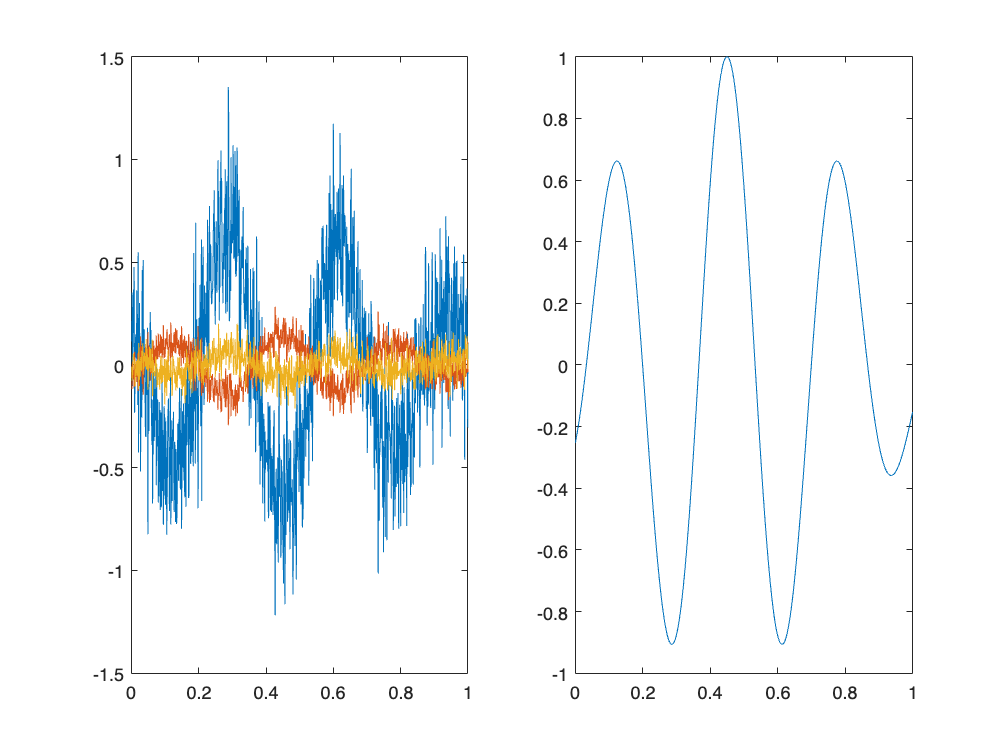

figure
subplot(1, 2, 1); plot(t, sbf(sel1110,:));
subplot(1, 2, 2); plot(t, s1);

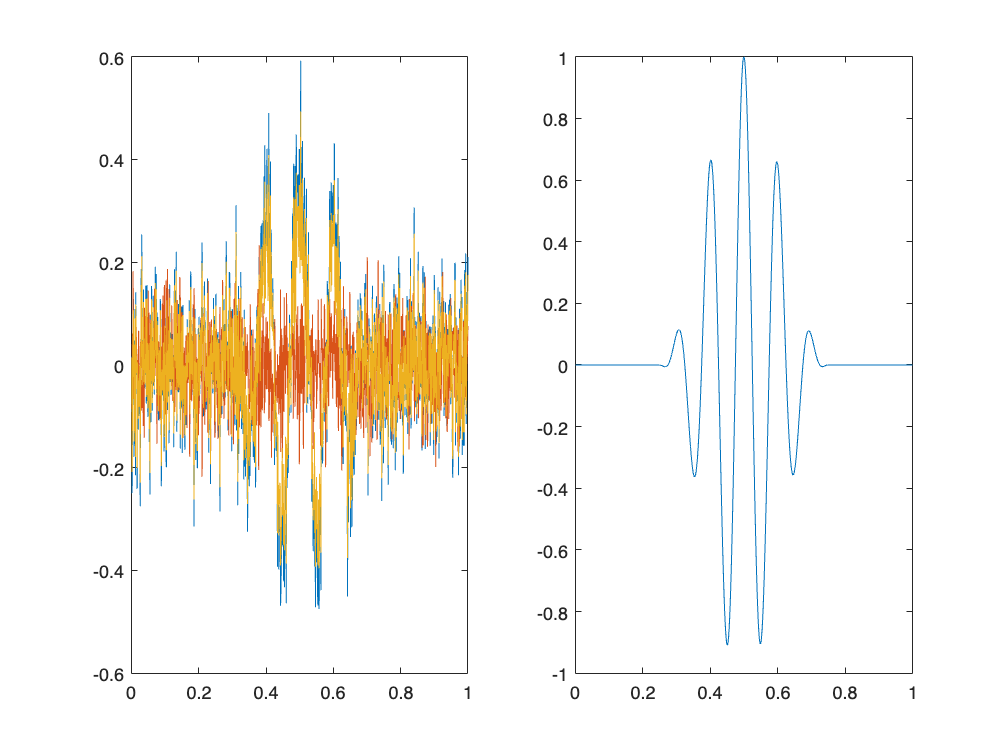

figure
subplot(1, 2, 1); plot(t, sbf(sel2342,:));
subplot(1, 2, 2); plot(t, s2);

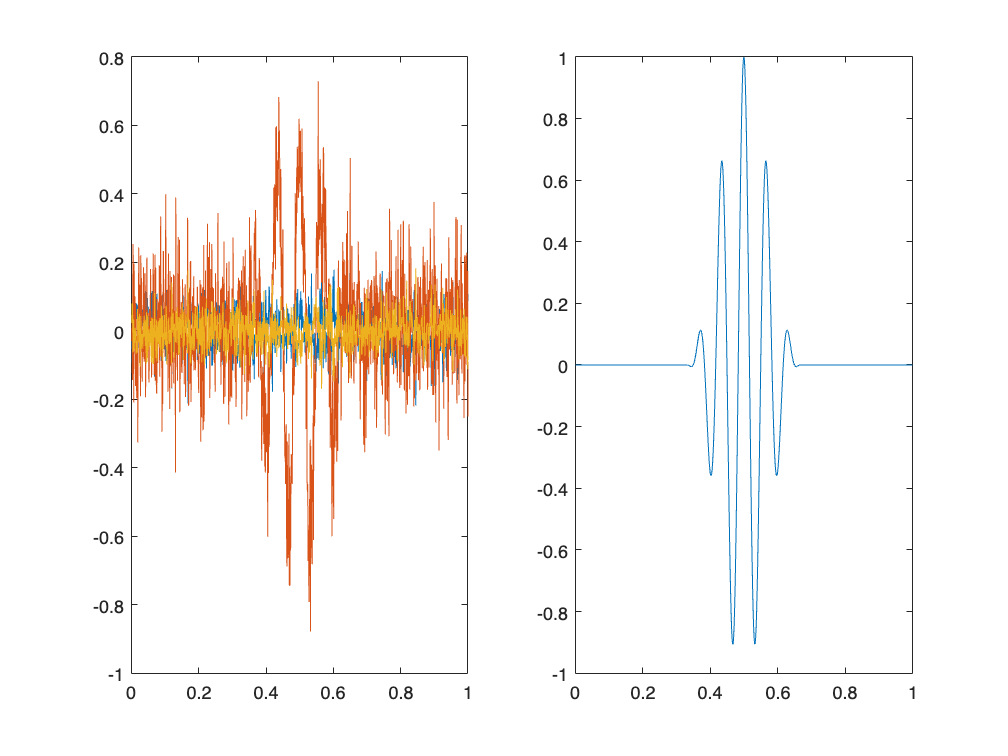

figure
subplot(1, 2, 1); plot(t, sbf(sel2352,:));
subplot(1, 2, 2); plot(t, s3);

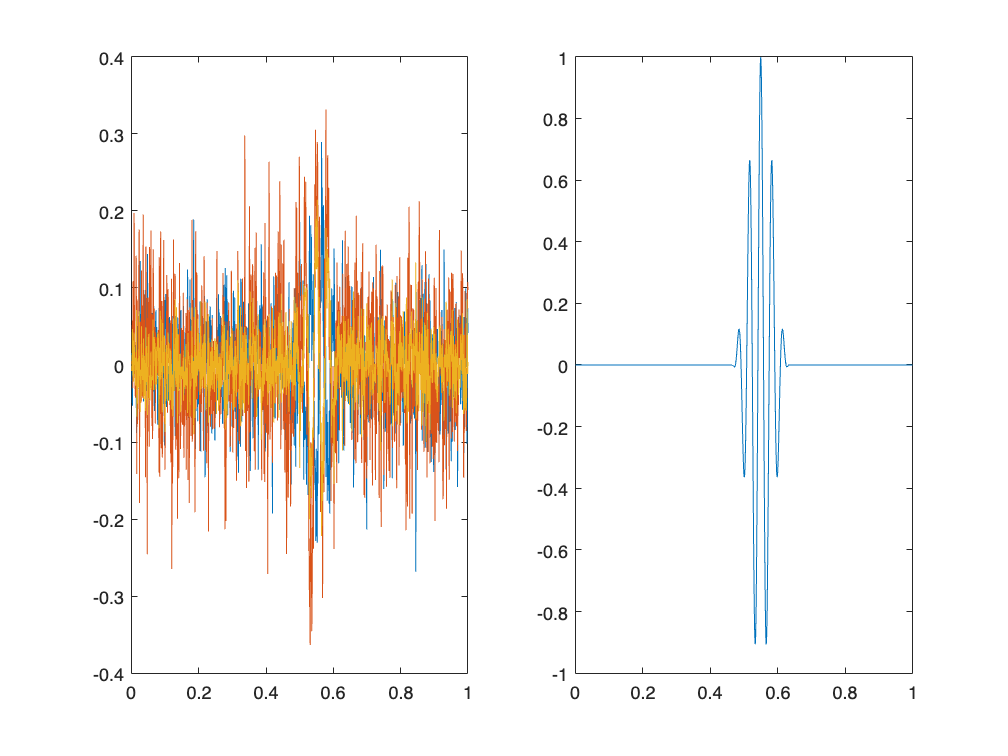

figure
subplot(1, 2, 1); plot(t, sbf(sel2674,:));
subplot(1, 2, 2); plot(t, s4);

As you may have noticed, the resulting time courses are still a bit noisy due to the noise in the data also being projected onto the estimated source time courses. Since we only have 1000 samples, the structure of the noise in the data is not so well estimated and hence cannot be so well suppressed. We can improve the noise suppression using a regularized estimate of the inverse covariance. We do that using Tikhonov regularization, also used in Ridge regression (see https://en.wikipedia.org/wiki/Ridge_regression). For that we add a certain amount of "identity matrix" to the covariance matrix prior to taking the inverse. The amount of regularization can be determined from the plot of the eigenvalues (or singluar values) of the covariance, also known as the scree plot (see https://en.wikipedia.org/wiki/Scree_plot).

iCr = inv(C + 1e-18*eye(301));

## 4 Beamformer features

After this section, you will

- Understand the depth bias of the beamformer, and its cause.

- Understand how in the typical application a contrast between two conditions is needed for a meaningful source reconstruction.

- Understand how the performance of the beamformer is affected by correlation of the source time courses.

## 4.1 Beamforming and depth bias

In the previous section we visualized the reconstructed time courses at the locations close to where we actually simulated the activity. In real applications, these locations of course are unknown, and we typically need to look for local maxima in the reconstructed 'image’. The quantity that is used is the filter output, i.e., the variance of the source time courses, which is also often referred to as the 'power’ of the sources. Apart from the fact that in real applications the data are usually quite noisy, causing difficulties in the estimation of the local maxima, there is an important feature of the beamformer, which further complicates the evaluation of peaks in the image. This is the so-called depth bias.

To illustrate this depth bias, we first restructure the source-reconstructed simulated data of section 3.2 in a data-structure that can be used by FieldTrip, so that we can use FieldTrip's visualization functionality. If you don’t have the `sbf` and `sourcemodel` variables in MATLAB memory anymore, you need to reconstruct these in order to be able to proceed.

In order to represent the reconstruction as an image, we need to express the variance of the sources at each of the locations in a single number. Recall that at each location of the 3-dimensional grid the source activity consists of three time courses, one for each 'cardinal’ x/y/z orientation. A common way to achieve this is to sum the variance across the three orientations. This is essentially the application of Pythagoras’ rule (without explicitly taking the square and the square root, since variance is already a 'squared’ value). With our sbf variable it is possible to do this in the following way. Note that this variable is a 'number of inside sources x 3’ times 'number of timepoints’ matrix. If we compute the variance across time (var(sbf, [], 2)) we end up with a vector, that in consecutive triplets contains the variance in the x/y/z orientation at the 'inside’ dipole locations of the sourcemodel. We can now efficiently create the variance for each location by using MATLAB’s reshape and sum functions:

pbf = var(sbf, [], 2);
pbf = reshape(pbf, 3, numel(pbf)/3);
pbf = sum(pbf, 1);

Take a moment to try and understand what is going on in the second and third line.

Now, create a FieldTrip structure of the 'source’ type, and use `ft_sourceplot` to visualize this.

source = [];
source.pos    = sourcemodel.pos;
source.dim    = sourcemodel.dim;
source.inside = sourcemodel.inside;
source.inside = reshape(source.inside, source.dim);
source.pow = zeros(size(source.pos, 1), 1);
source.pow(source.inside) = pbf;
source.pow = reshape(source.pow, source.dim);

cfg = [];
cfg.funparameter = 'pow';
cfg.method = 'slice';
cfg.nslices = 10;
cfg.funcolorlim = [0 0.2];
ft_sourceplot(cfg, source);

***Include the figure that you just created in your answers.***

What you see now is a set of slices through the spherical volume conductor, where each slice is parallel to the xy-plane. It starts at the left-lower bottom with the slice that has the lowest z-coordinate, and ends at the upper right with the crown of our 'simulated’ head. The x-axis is running from left to right, and the y-axis is running from bottom to top.

The most prominent feature in this image is the enormous 'blob’ in the middle of the 'head’. This represents the depth bias of the beamformer, and is an important motivation for why most successful applications of the beamformer always involve the reconstruction of a contrast between two conditions (another important motivation is that we are usually interested in the features in our data that change as a consequence of an experimental manipulation, which by construction always involves the comparison across two (or more) experimental conditions). In this simulated data example with a relatively high signal-to-noise ratio of the data, admittedly three out of the four simulated sources are visible.

The depth bias is directly caused by the unit gain constraint of the spatial filter. The further away the source is from the sensors, the smaller the numbers in the leadfield (why?). If the dot-product between the spatial filter and the leadfield is required to be 1, the small values in a deep source’s leadfield need to be counterbalanced by large values in the spatial filter. As a direct consequence the spatial filter’s output (`w'*C*w`) will be much larger for a deep source than for a more superficial source.

## 4.2 Accounting for depth bias: computing a contrast

In the previous section we have seen that the depth bias is related to the fact that the spatial filters for deep sources have much higher values than the spatial filters for superficial sources. The depth bias is therefore a feature of the spatial filters. One way to account for this is to normalize the estimated source power by an estimate of how noise projects through the spatial filters. This normalized quantity is known as the 'neural activity index’, but in real data applications this usually does not work that well. The reason is that a good estimate of the noise is difficult to obtain, and usually the noise covariance is assumed to be a scaled identity matrix (this reflects noise to be uncorrelated across channels, with the same variance for each of the channels), which is far from reality. A better strategy is to compute a contrast between two conditions. The idea is that the features in the data that are the same across conditions (such as the depth bias) will cancel each other when making the contrast.

We will use the variables `sensordata`, `sourcemodel` and `L` that we also used in section 3. We also need the leadfields and source timecourses that we used for the simulations. If you don’t have these variables anymore in MATLAB memory, you should re-create them.

Now we will simulate data from a 'second’ condition (compared to the original variable sensordata), where the sources have the exact same locations and time courses, but the amplitude of two sources is decreased, and the amplitude of the two other sources is increased, relative to the 'first’ condition.

sensordata2 = 1.25 .* leadfield1*s1 + ...
              0.80 .* leadfield2*s2 + ...
              0.80 .* leadfield3*s3 + ...
              1.25 .* leadfield4*s4 + ...
              randn(301, 1000)*1e-9;

We will now compute the spatial filters using the covariance estimated from the data combined across the two conditions. In this way we will end up with a single set of spatial filters, and thus, in comparing across the two conditions, we ensure that the depth bias is the same for condition 1 and 2. The covariance of the data combined across the 2 conditions can be computed in several ways, e.g. by averaging the single condition covariances. Here, we first concatenate the data and subsequently compute the covariance. Now we will use the MATLAB cov function, rather than computing the covariance 'by hand’ (i.e., by first computing the mean across time etc.).

C2 = cov([sensordata sensordata2]');
iCr2 = inv(C2 + eye(301)*2e-18);

for ii=1:size(L, 2)/3
  indx = (ii-1)*3 + (1:3);
  Lr = L(:, indx);  % Lr is the Nx3 leadfield matrix for source r
  wbf(indx,:) = pinv(Lr'*iCr2*Lr)*Lr'*iCr2;
end

sbf1 = wbf * sensordata;
sbf2 = wbf * sensordata2;

pbf1 = var(sbf1, [], 2);
pbf1 = reshape(pbf1, 3, numel(pbf1)/3);
pbf1 = sum(pbf1, 1);

pbf2 = var(sbf2, [], 2);
pbf2 = reshape(pbf2, 3, numel(pbf2)/3);
pbf2 = sum(pbf2, 1);

We can now create a FieldTrip style source-structure, and store in the field pow a measure of the difference between condition 1 and 2.

source = [];
source.pos    = sourcemodel.pos;
source.dim    = sourcemodel.dim;
source.inside = sourcemodel.inside;
source.inside = reshape(source.inside, source.dim);
source.pow    = zeros(size(source.pos, 1), 1);
source.pow(source.inside) = (pbf1-pbf2)./((pbf1+pbf2)/2);
source.pow = reshape(source.pow, source.dim);

cfg = [];
cfg.funparameter = 'pow';
cfg.method = 'slice';
cfg.nslices = 10;
cfg.funcolorlim = [-0.3 0.3];
ft_sourceplot(cfg, source);

***Include the figure that you just created in your answers.***

## 4.3 Beamforming and correlated sources

An unfortunate characteristic feature of the beamformer is its inability to deal with strongly correlated sources. This is a direct consequence of the fact that, in the presence of correlated sources, the leadfield outer products of the sources that are correlated contribute significantly to the sensor level covariance matrix (see section 2.2). As a result, the spatial filters, which aim to suppress interfering (but uncorrelated) activity originating from other locations lead to a distortion of the true source time courses. In this section we will start from a fresh simulation, so you’d best issue a `clear all` command before you proceed.

First, we create some sensor data:

sensors = ni2_sensors('type', 'meg');
headmodel = ni2_headmodel('type', 'spherical', 'nshell', 1);
leadfield1 = ni2_leadfield(sensors, headmodel, [-5.3 0 5.9 1 0 0]); % position 2342 in grid
leadfield2 = ni2_leadfield(sensors, headmodel, [4.9 0 6.2 0 1 0]);  % position 2352 in grid

% create the time course of activation
[s1, t] = ni2_activation('latency', .5, 'frequency', 10);
[s2, t] = ni2_activation('latency', .49, 'frequency', 10);

% create the sensor data
sensordata = leadfield1*s1 + ...
             leadfield2*s2 + ...
             randn(301, 1000)*0.04e-9;

Now we can assess the correlation between s1 and s2, and we will note that it is significant:

c = corr(s1', s2');

***What is the correlation?***

***Plot the source timecourse s1 and s2 in a single figure.***

We can make a scree plot of the eigenvalues of the sensor covariance. It reveals that there is largely only one source component contributing to the data

v = svd(cov(sensordata'));
figure; plot(v(1:10), 'o')

***Try making sensordata  with more and with less correlated sources.***